Surf plots for the range of parameters in Section 2

The objective here is to show that the surfaces are smooth so we can get away with a simple hill-climbing algorithm to find the maximum

"dat" can be a combination of dat2 and dat2_kin tables

%cleanup
dat = dat2_surface;
dat = dat(dat.kcat_cel <= 600,:);

%Calculate the RMSE of the log biomass vs experimental data
[nrows,~] = size(dat);
rmse = zeros(nrows,1);
for i = 1:nrows
    t_exp = ivd.denhaan.ctdat;
    b_exp = ivd.denhaan.gdw;
    t_sim = dat.t{i};
    b_sim = dat.biomass{i};
    b_sim = b_sim(ismember(t_sim,t_exp));
    logbexp = log10(b_exp);
    logbsim = log10(b_sim);
    summation = 0;
    n = length(logbexp);
    for j = 1:n
        val = logbsim(j) - logbexp(j);
        val = val^2;
        summation = summation + val;
    end
    rmse(i) = sqrt(summation/n);
end
dat.rmse = rmse;


alphas = log(unique(dat.alpha));
a = mode(dat.alpha);
log(a)

ans = -3.2000

d = dat(dat.alpha == a,:);
kcat = d.kcat_cel;
km = d.km_cel;
rmse = d.rmse;

%is the plateau actually flat? if yes, this sum should be high
sum(rmse == min(rmse))

ans = 4

f = find(rmse == min(rmse))

f =     25
    52
   224
   227


for i = f
    kcat_km_rmse = [kcat(i), km(i), rmse(i)]
end

kcat_km_rmse =    13.5000    0.0055    0.5272
   27.0000    0.0137    0.5272
   20.0000    0.0065    0.5272
   20.0000    0.0092    0.5272


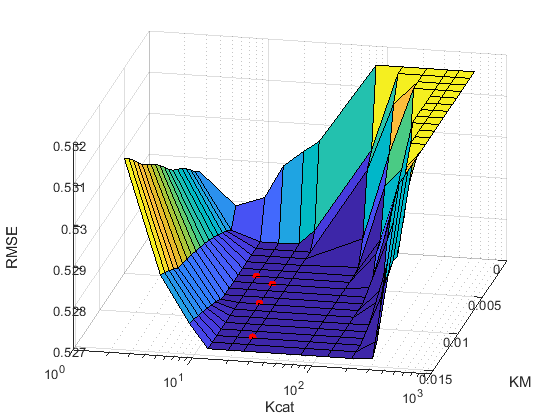

figure();
h = axes;
[p,X,Y,Z] = surfArrays(kcat,km,rmse);
xlabel('Kcat');
ylabel('KM');
zlabel('RMSE');
set(h,'Xdir','reverse');
set(h,'XScale','log');
hold on;
for i = f
    scatter3(kcat(i),km(i),rmse(i),'r','filled')
end
hold off;

view([-168.00000 29.40000])

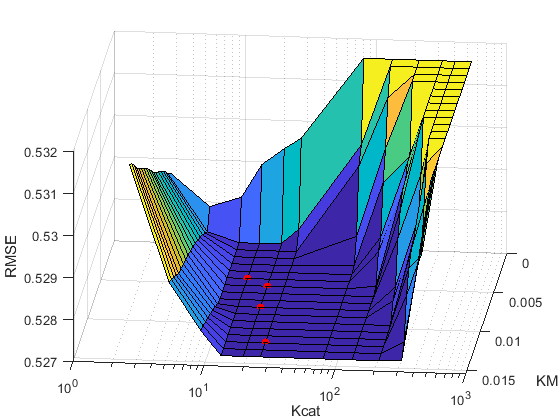


figure();
h = axes;
[p,X,Y,Z] = surfArrays(km,kcat,rmse);
ylabel('Kcat');
xlabel('KM');
zlabel('RMSE');
%set(h,'Xdir','reverse');
set(h,'YScale','log');
hold on;
for i = f
    scatter3(km(i),kcat(i),rmse(i),'r','filled')
end
hold off;

view([96.00000 30.00000])

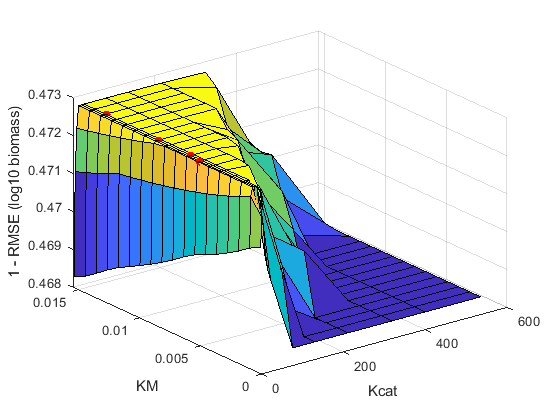


[p,X,Y,Z] = surfArrays(kcat,km,1-rmse);
xlabel('Kcat');
ylabel('KM');
zlabel('1 - RMSE (log10 biomass)');
hold on;
for i = f
    scatter3(kcat(i),km(i),1-rmse(i),'r','filled')
end
hold off;